# Euler

f = @(t,y) -2*t^3+12*t^2-20*t+8.5

f = function_handle with value:
    @(t,y)-2*t^3+12*t^2-20*t+8.5


%f = @(t, y) 4*exp(0.8*t)-0.5*y
t0 = 0

t0 = 0

tf = 4

tf = 4

h = 0.5

h = 0.5000

y0 = 1

y0 = 1


syms y(t)
eqn = diff(y, t) == -2*t^3+12*t^2-20*t+8.5

$$eqn(t) = \frac{\partial }{\partial t}y\left(t\right)=-2\,t^{3}+12\,t^{2}-20\,t+\frac{17}{2}$$

cond = y(0) == 0

$$cond = y\left(0\right)=0$$

sol = dsolve(eqn, cond)

$$sol = -\frac{t^{4}}{2}+4\,t^{3}-10\,t^{2}+\frac{17\,t}{2}$$


hold on
[t, y] = odeEuler(f, y0, t0, tf, h);

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y =     1.0000    5.2500    5.8750    5.1250    4.5000    4.7500    5.8750    7.1250    7.0000


plot(t, y) 
[t1, y1] = odeMidpoint(f, y0, t0, tf, h);

t1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y1 =     1.0000    3.1094    2.8125    1.9844    1.7500    2.4844    3.8125    4.6094    3.0000


plot(t1, y1)
[t2, y2] = odeHeun(f, y0, t0, tf, h);

t2 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y2 =     1.0000    3.4375    3.3750    2.6875    2.5000    3.1875    4.3750    4.9375    3.0000


plot(t2, y2)
[t3, y3] = odeHeunIterativo(f, y0, t0, tf, h);

t3 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y3 =     1.0000    3.4375    3.3750    2.6875    2.5000    3.1875    4.3750    4.9375    3.0000


plot(t3, y3)
[t4, y4] = odeRK4(f, y0, t0, tf, h);

t4 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y4 =     1.0000    3.2188    3.0000    2.2188    2.0000    2.7188    4.0000    4.7188    3.0000


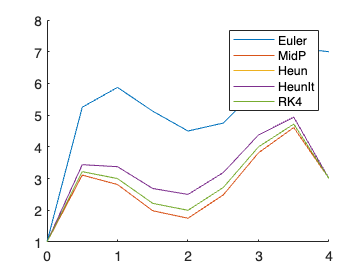

plot(t4, y4)

legend('Euler', 'MidP', 'Heun', 'HeunIt', 'RK4')

hold off


f = @(t,y) -3*y

f = function_handle with value:
    @(t,y)-3*y


y0 = 1

y0 = 1

t0 = 0

t0 = 0

tf = 2

tf = 2

h = 0.05

h = 0.0500

[t, y]=odeMilne(f, y0, t0, tf, h)

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


y =     1.0000    0.8607    0.7408    0.6376    0.5488    0.4724    0.4066    0.3499    0.3012    0.2592    0.2231    0.1920    0.1653    0.1423    0.1225    0.1054    0.0907    0.0781    0.0672    0.0578    0.0498    0.0429    0.0369    0.0317    0.0273    0.0235    0.0202    0.0174    0.0150    0.0129    0.0111    0.0096    0.0082    0.0071    0.0061    0.0052    0.0045    0.0039    0.0033    0.0029    0.0025


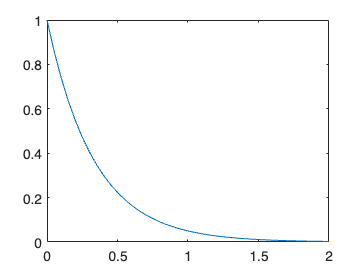

plot(t, y)


M = [0 1;0.15 0];
T0 = 240;
x0 = 0;
xf = 10;
N = 1000;
h = (xf- x0)/(N - 1);
z = -60;
f = @(t, Tz) M*Tz;
d = odeShooting(f, h, x0, xf,T0, z)

d = 2.0497e+03

function [t,y]=odeEuler(f,y0,t0,tf,h)
    t=t0:h:tf;
    y = zeros(size(t));
    n=length(t);
    y(1)=y0;
    for i=1:1:n-1
       phi=f(t(i),y(i));
       y(i+1)=y(i)+h*phi;
    end
end

function [t,y]=odeMidpoint(f,y0,t0,tf,h)
    h2=h/2;
    t=t0:h:tf;
    n=length(t);
    y=zeros(size(t));
    y(1)=y0;
    for i=1:n-1
        y2=y(i)+f(t(i),y(i))*h2;
        phi=f(t(i)+h2,y2);
        y(i+1)=y(i)+phi*h;
    end
end

function [t,y] = odeHeun(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(1,n);
    y(1)=y0;
    for i=1:1:n-1
        s1=f(t(i),y(i)); 
        yp=y(i)+h*s1; %predictor
        s2=f(t(i)+h,yp); %corrector 
        phi=(s1+s2)/2;
        y(i+1)=y(i)+phi*h;
    end    
end

function [t,y] = odeHeunIterativo(f,y0,t0,tf,h)
    MAX=100;
    tol=eps;
    t=t0:h:tf;
    n=length(t);
    y=zeros(1,n);
    y(1)=y0;
    for i=1:1:n-1
        y(i+1)=y(i)+f(t(i),y(i)*h);
        j=0;
        cond=true;
        while cond
            yp=y(i+1);
            y(i+1)=y(i)+0.5*(f(t(i),y(i))+f(t(i+1),y(i+1)))*h;
            j=j+1;
            cond = abs(y(i+1)-yp) > tol*abs(y(i+1)) && j<MAX;
        end
    end    
end

function [t,y] = odeMilne(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    [~,tempY] = odeRK4(f,y0,t0,tf,h);
    y(:,2) = tempY(2);
    y(:,3) = tempY(3);
    y(:,4) = tempY(4);
    
    for i = 4:n-1
        y(:,i+1) = y(:,i-3) + (4*h/3)*(2*f(t(i),y(:,i)) - f(t(i-1),y(:,i-1)) + 2*f(t(i-2),y(:,i-2))); %si lo sobreescribe, pa que?
        y(:,i+1) = y(:,i-1) + (h/3)*(f(t(i-1),y(:,i-1)) + 4*f(t(i),y(:,i)) + f(t(i+1),y(:,i+1)));
    end
end

function d = odeShooting(f, h, x0, xf, T0, z)
    y0 =[T0, z];
    [t, y]=odeRK4(f, y0, x0, xf, h);
    d = y(1, end);
end

function [t,y]=odeRK4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end